# Actividad 6.1 (Seguimiento de Trayectorias)

Bruno Manuel Zamora Garcia A01798275

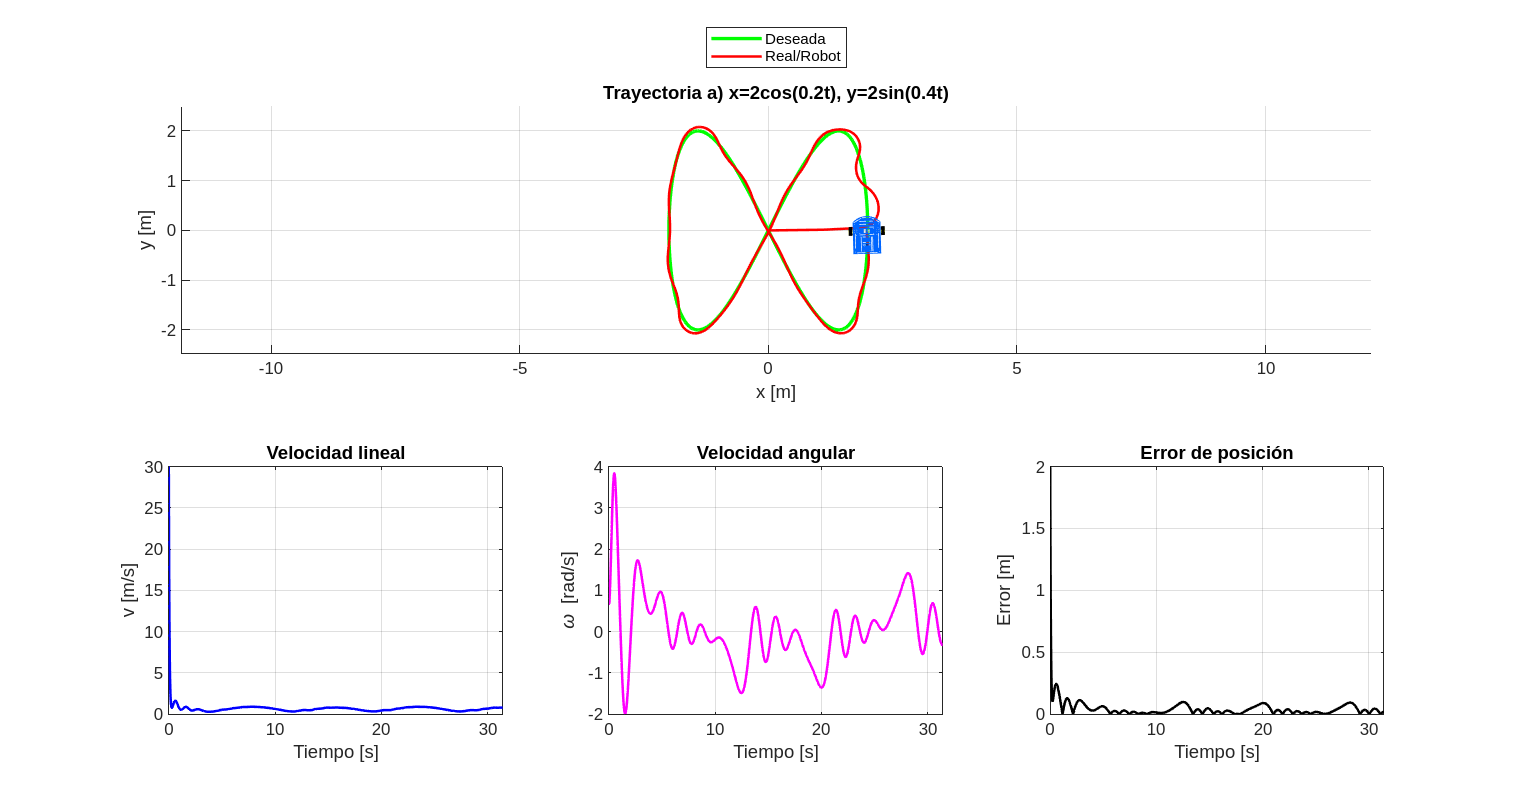

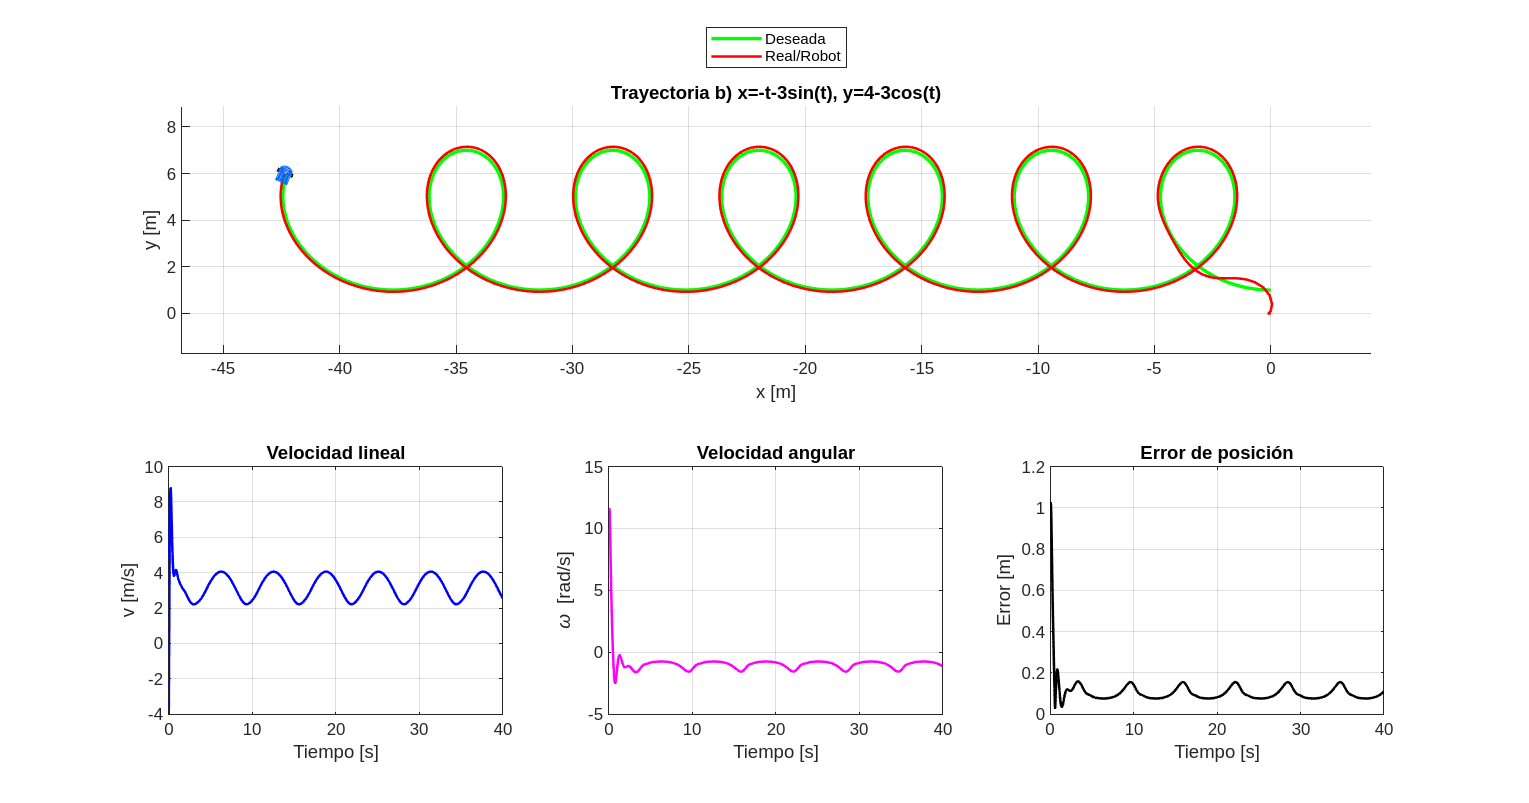

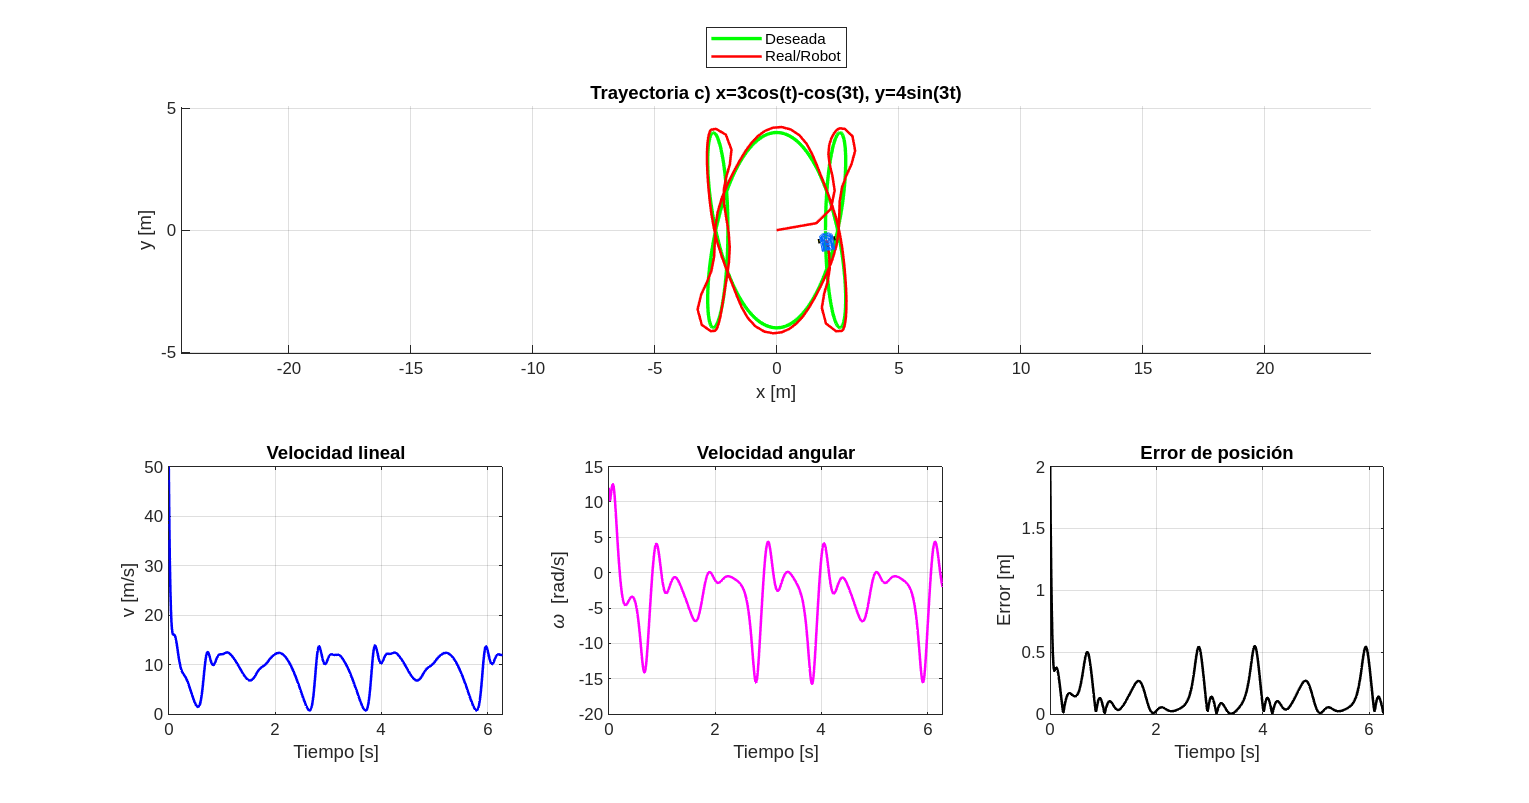

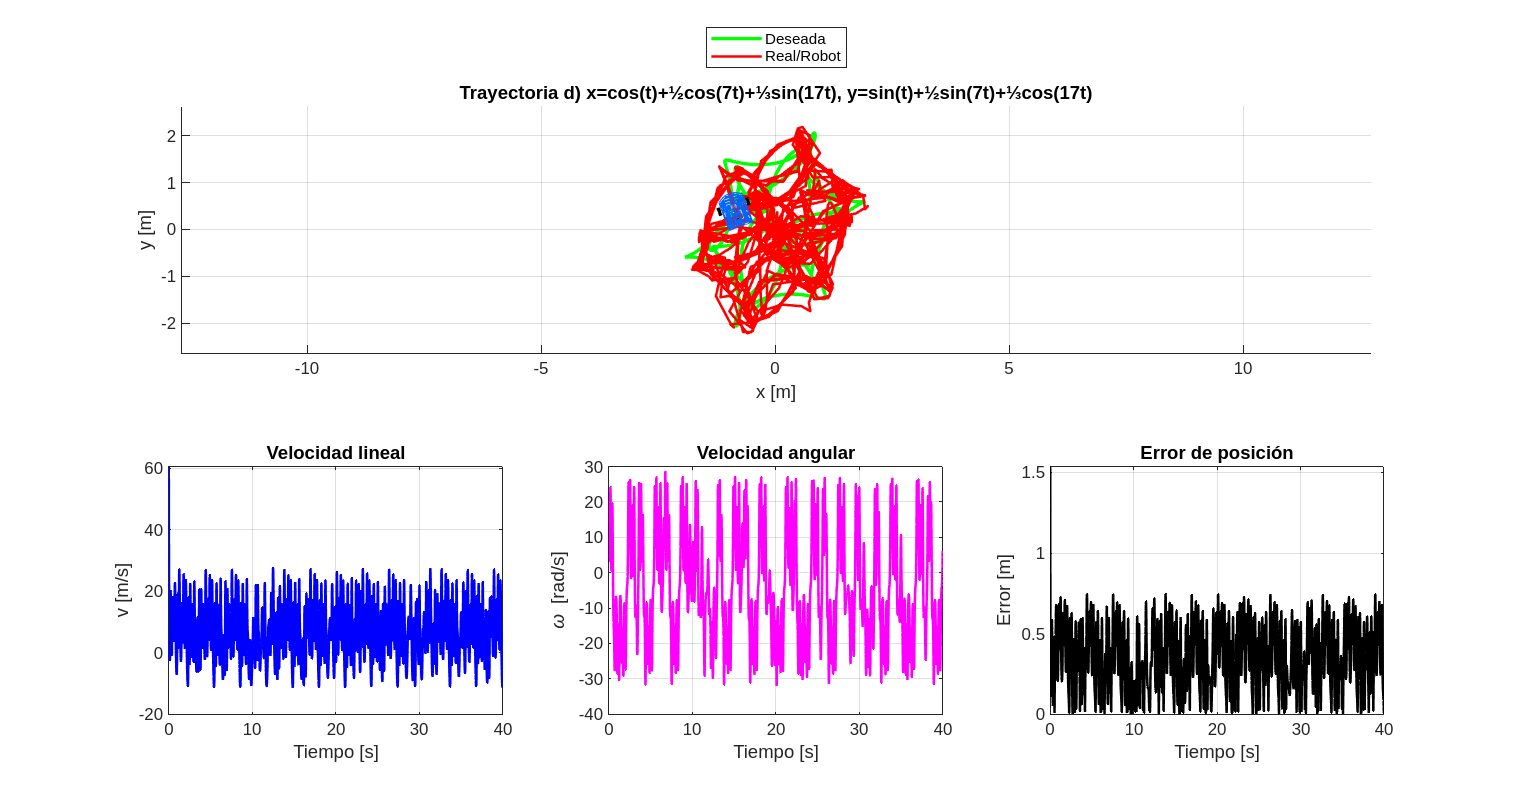

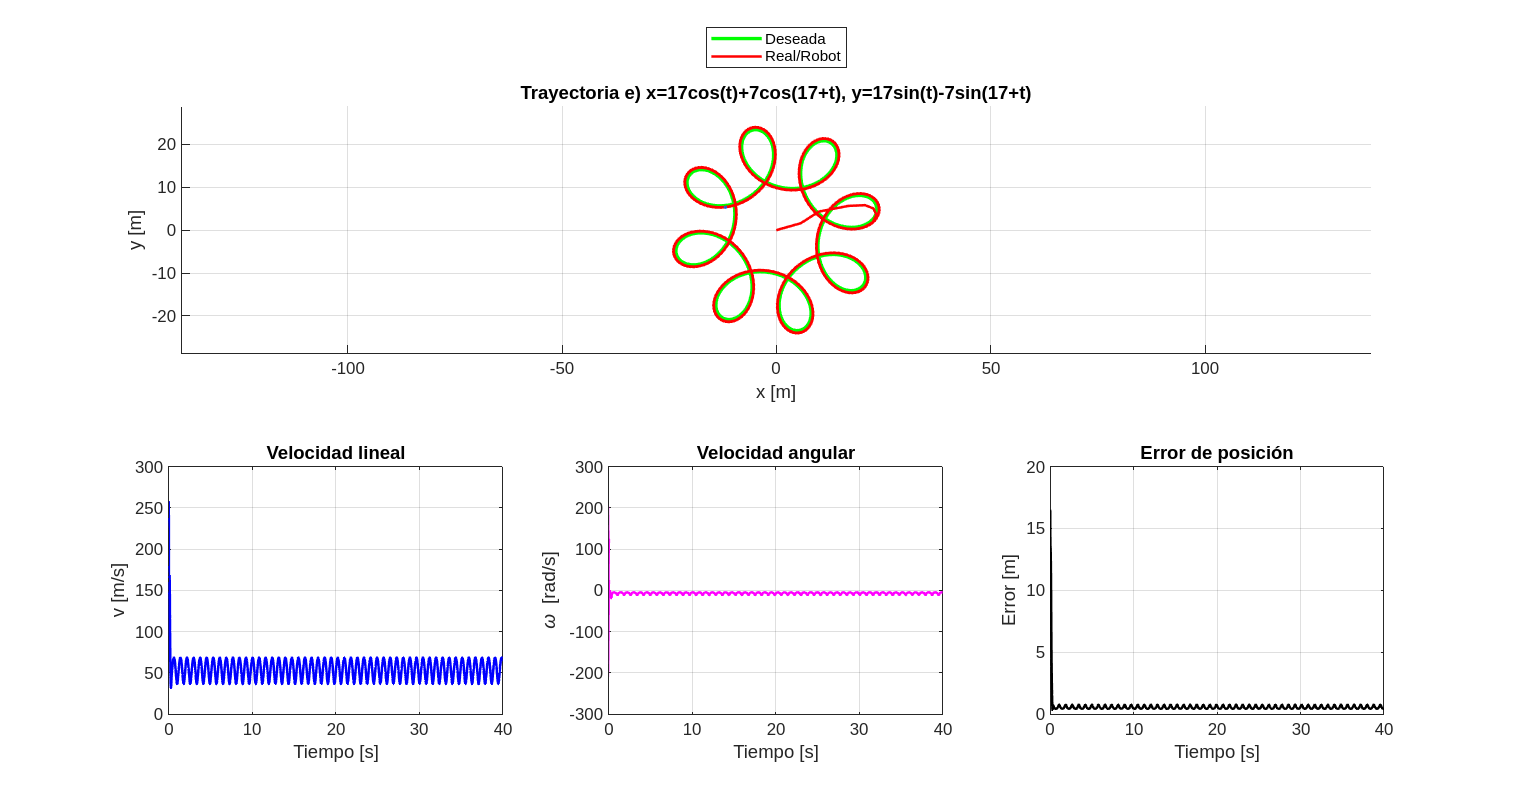

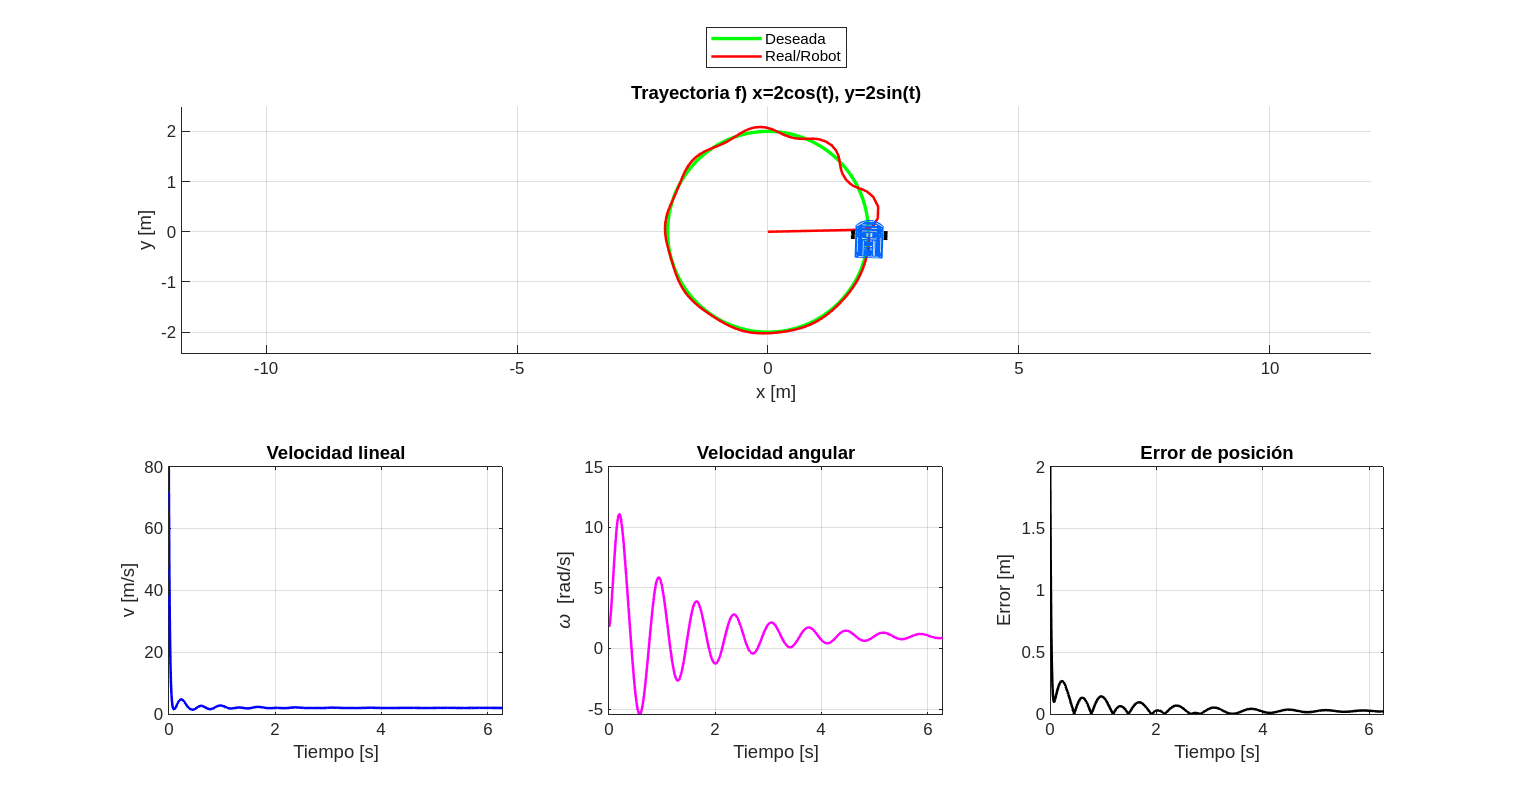

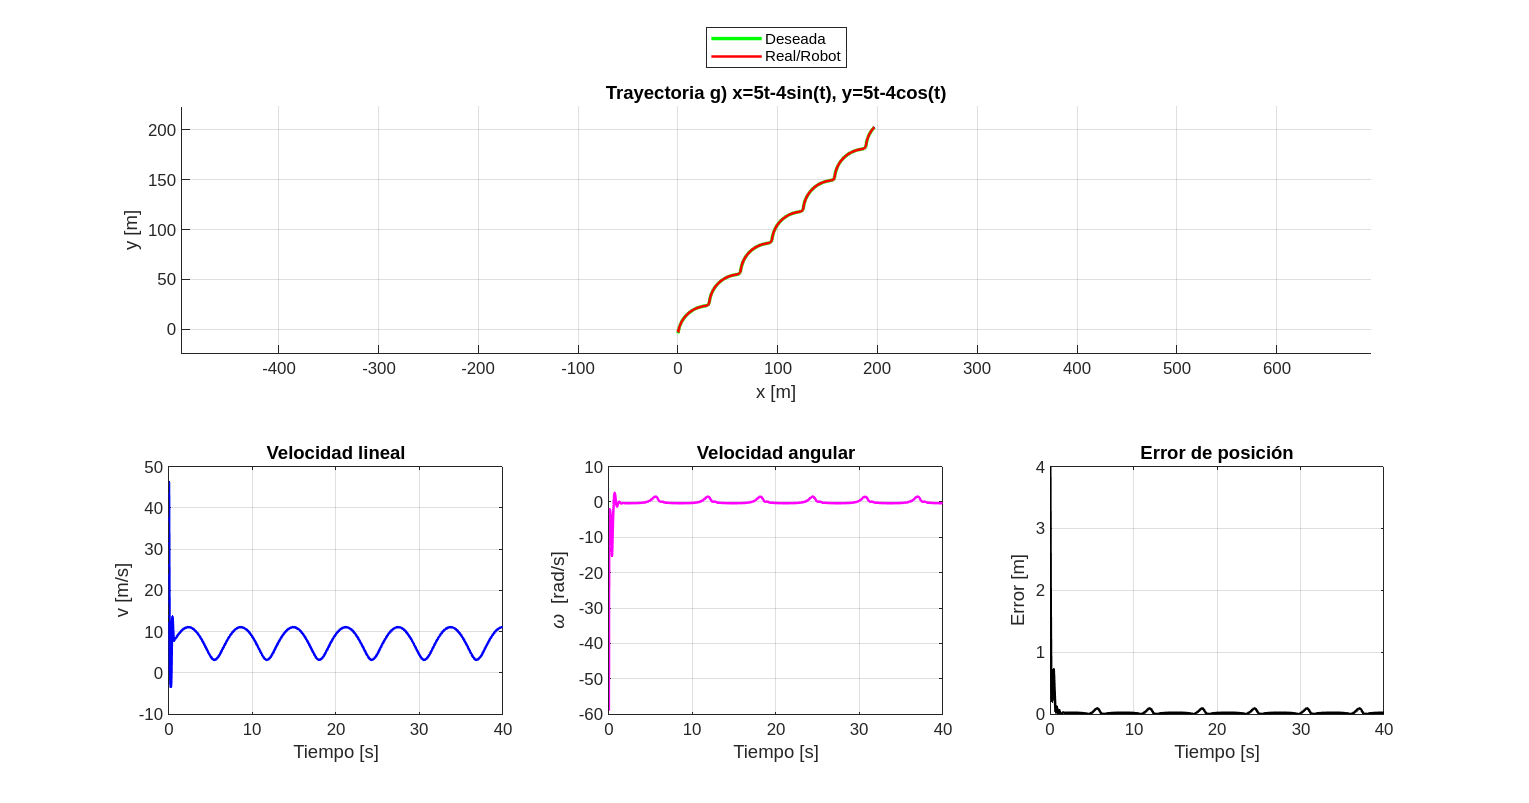

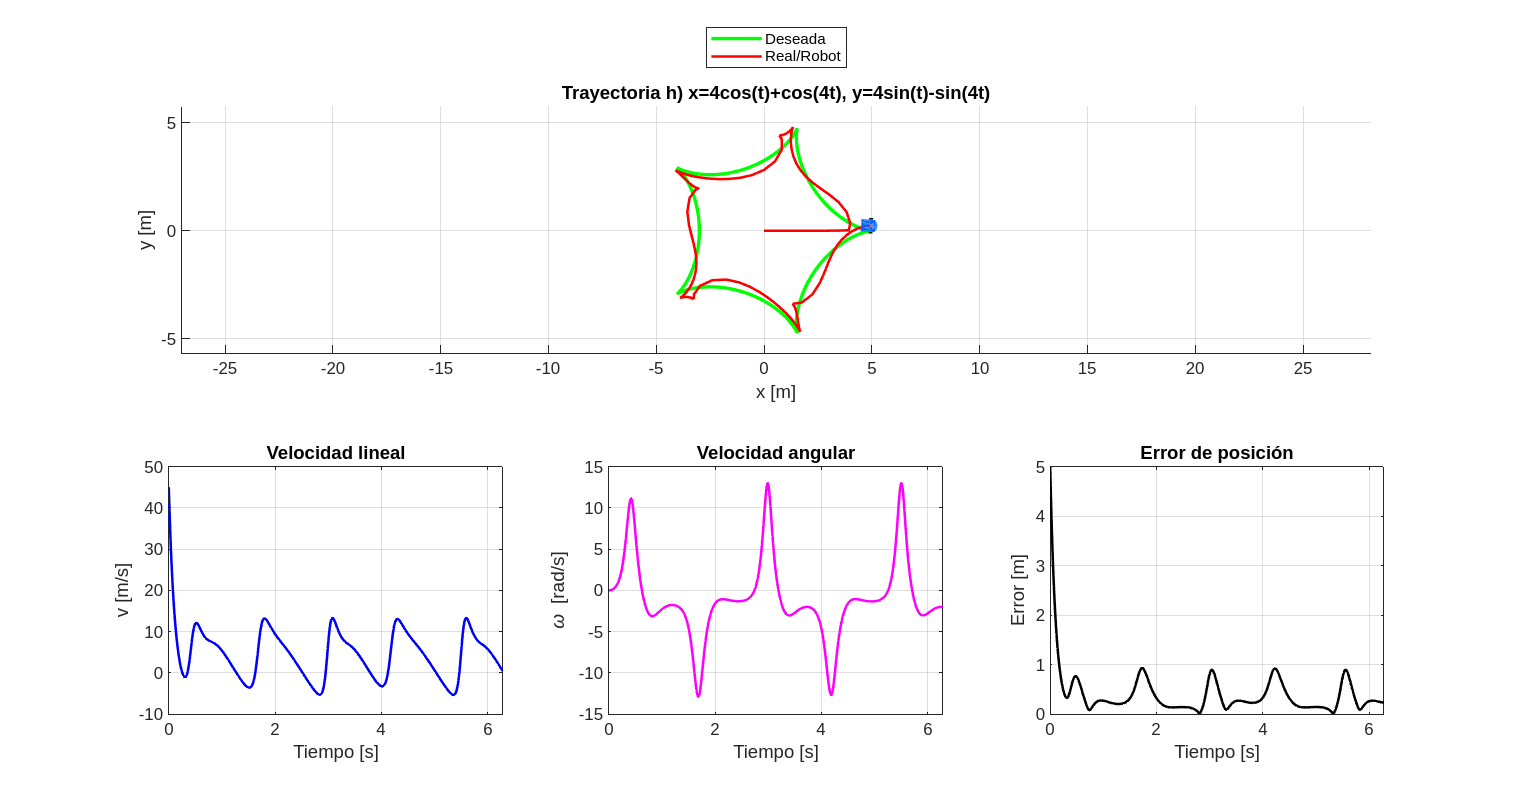

% Actividad 6.1 (Seguimiento de Trayectorias)
% Bruno Manuel Zamora Garcia A01798275
% Este script realiza el seguimiento automático de 11 trayectorias distintas
% para un robot diferencial, con tiempos finales, ganancias K y visualización
% diseñados según los requisitos de cada ejercicio.
clear; close all; clc

%% Parámetro de muestreo
% El paso de muestreo ts=0.01 s ofrece un buen balance entre precisión
%y carga computacional, asegurando trayectorias suaves.
ts = 0.01;  % paso fijo [s]

%% Bucle principal: recorre trayectorias del 1 al 11
% 1–8: incisos a–h originales  |  9: hexágono  |  10: flor  |  11: corazón
for caseNum = 1:11

    %% Selección de trayectoria y parámetros específicos
    % Defino el vector de tiempo t, la trayectoria deseada (hxd, hyd),
    % sus derivadas (hxdp, hydp) y la matriz de ganancias K.
    switch caseNum
        case 1  % a) círculo modulable
            titleStr = 'a) x=2cos(0.2t), y=2sin(0.4t)';
            tfCase   = 2*pi/0.2;       % un ciclo completo en x
            t        = 0:ts:tfCase;
            hxd      = 2*cos(0.2*t);  % posición deseada en x
            hxdp     = -2*0.2*sin(0.2*t); % derivada de x
            hyd      = 2*sin(0.4*t);  % posición deseada en y
            hydp     = 2*0.4*cos(0.4*t);  % derivada de y
            K        = [15 0; 0 15];  % ganancia proporcional para seguimiento estable

        case 2  % b) desplazamiento + sinusoide
            titleStr = 'b) x=-t-3sin(t), y=4-3cos(t)';
            t        = 0:ts:40;       % tiempo fijo de 40s
            hxd      = -t - 3*sin(t);
            hxdp     = -1 - 3*cos(t);
            hyd      = 4 - 3*cos(t);
            hydp     = 3*sin(t);
            K        = [10 0; 0 10];  % ganancia moderada para suavizar la oscilación

        case 3  % c) tres armónicos
            titleStr = 'c) x=3cos(t)-cos(3t), y=4sin(3t)';
            tfCase   = 2*pi;
            t        = 0:ts:tfCase;
            hxd      = 3*cos(t) - cos(3*t);
            hxdp     = -3*sin(t) + 3*sin(3*t);
            hyd      = 4*sin(3*t);
            hydp     = 12*cos(3*t);
            K        = [25 0; 0 25];  % mismo valor para ambos ejes

        case 4  % d) suma de armónicos 7t y 17t
            titleStr = 'd) x=cos(t)+½cos(7t)+⅓sin(17t), y=sin(t)+½sin(7t)+⅓cos(17t)';
            t        = 0:ts:40;       % cubre varias repeticiones
            hxd      = cos(t) + .5*cos(7*t) + (1/3)*sin(7*t) + (1/3)*sin(17*t);
            hyd      = sin(t) + .5*sin(7*t) + (1/3)*sin(7*t) + (1/3)*cos(17*t);
            hxdp     = -sin(t) -3.5*sin(7*t) + (7/3)*cos(7*t) + (17/3)*cos(17*t);
            hydp     =  cos(t) +3.5*cos(7*t) + (7/3)*cos(7*t) - (17/3)*sin(17*t);
            K        = [35 0; 0 35];  % ganancia elevada ante complejidad alta

        case 5  % e) combinación con fase desplazada
            titleStr = 'e) x=17cos(t)+7cos(17+t), y=17sin(t)-7sin(17+t)';
            t        = 0:ts:40;
            hxd      = 17*cos(t) + 7*cos(17 + 7*t); 
            hxdp = -17*sin(t) - 7*7*sin(17 + 7 *t);
            hyd      = 17*sin(t) - 7*sin(17 + 7*t); 
            hydp =  17*cos(t) - 7*7*cos(17 + 7*t);
            K        = [14 0; 0 14];  % ganancia equilibrada para fase desplazada

        case 6  % f) círculo simple
            titleStr = 'f) x=2cos(t), y=2sin(t)';
            tfCase   = 2*pi;
            t        = 0:ts:tfCase;
            hxd      = 2*cos(t);
            hxdp     = -2*sin(t);
            hyd      = 2*sin(t);
            hydp     = 2*cos(t);
            K        = [40 0; 0 40];  % alta ganancia para precisión circular

        case 7  % g) ondulación lineal
            titleStr = 'g) x=5t-4sin(t), y=5t-4cos(t)';
            t        = 0:ts:40;
            hxd      = 5*t - 4*sin(t);
            hxdp     = 5 - 4*cos(t);
            hyd      = 5*t - 4*cos(t);
            hydp     = 5 + 4*sin(t);
            K        = [16 0; 0 16];  % ganancia intermedia para acción lineal

        case 8  % h) superposición cosenos
            titleStr = 'h) x=4cos(t)+cos(4t), y=4sin(t)-sin(4t)';
            tfCase   = 2*pi;
            t        = 0:ts:tfCase;
            hxd      = 4*cos(t) + cos(4*t);
            hxdp     = -4*sin(t) - 4*sin(4*t);
            hyd      = 4*sin(t) - sin(4*t);
            hydp     = 4*cos(t) - 4*cos(4*t);
            K        = [9 0; 0 9];   % ganancia baja para evitar oscilación excesiva

        case 9  % hexágono mejorado
            titleStr = '9) Hexágono lado=1 (mejorado)';
            L        = 1; V = 0.1;
            T_seg    = L/V;
            pasos    = round(1.5 * T_seg / ts); % 50% más resolución en esquinas
            ang      = (0:5)*pi/3;
            px = cos(ang); py = sin(ang);
            hxd = []; hyd = []; hxdp = []; hydp = [];
            for i = 1:6
                xi = px(i); yi = py(i);
                xf = px(mod(i,6)+1); yf = py(mod(i,6)+1);
                vx = (xf - xi)/T_seg;
                vy = (yf - yi)/T_seg;
                hxd  = [hxd,  linspace(xi,xf,pasos)];
                hyd  = [hyd,  linspace(yi,yf,pasos)];
                hxdp = [hxdp, vx*ones(1,pasos)];
                hydp = [hydp, vy*ones(1,pasos)];
            end
            t = (0:length(hxd)-1)*ts;
            K = [30 0; 0 30];  % ganancia alta para esquinas bien marcadas

        case 10 % flor paramétrica
            titleStr = '10) Flor r=a·sin(4t)';
            a = 10; kf = 4;
            tfCase = 2*pi;
            t      = 0:ts:tfCase;
            r      = a*sin(kf*t);
            hxd    = r.*cos(t);
            hyd    = r.*sin(t);
            dr     = a*kf*cos(kf*t);
            hxdp   = dr.*cos(t) - r.*sin(t);
            hydp   = dr.*sin(t) + r.*cos(t);
            K      = [15 0; 0 15];  % ganancia estándar para curvas suaves

        case 11 % corazón paramétrico
            titleStr = '11) Corazón paramétrico';
            t        = linspace(0,2*pi,round(2*pi/ts));
            x_raw    = 16*sin(t).^3;
            y_raw    = 13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t);
            hxd      = (15/16)*x_raw;
            hyd      = (13/17)*y_raw;
            hxdp     = [diff(hxd)/ts, 0];
            hydp     = [diff(hyd)/ts, 0];
            K        = [12 0; 0 12]; % ganancia equi.
    end

    %% Inicialización de vectores de estado
    % Preparación de variables para el lazo de simulación\    
    N     = numel(t);
    x1    = zeros(1,N); y1 = zeros(1,N); phi = zeros(1,N);
    hx    = zeros(1,N); hy = zeros(1,N);
    v     = zeros(1,N); w  = zeros(1,N);
    Error = zeros(1,N);
    x1(1)=0; y1(1)=0; phi(1)=0; hx(1)=0; hy(1)=0;

    %% Lazo de control
    % Aplica ley proporcional en espacio de velocidades y Euler para integrar
    for k = 1:N
        e        = [hxd(k)-hx(k); hyd(k)-hy(k)];               % error posición
        Error(k) = norm(e);                                    % magnitud del error
        J        = [cos(phi(k)) -sin(phi(k));                 % jacobiana rotacional
                    sin(phi(k))  cos(phi(k))];
        u        = pinv(J)*( [hxdp(k); hydp(k)] + K*e );       % ley de control
        v(k)     = u(1); w(k) = u(2);
        phi(k+1) = phi(k) + w(k)*ts;                          % Euler orient.
        x1(k+1)  = x1(k) + v(k)*cos(phi(k))*ts;               % Euler en x
        y1(k+1)  = y1(k) + v(k)*sin(phi(k))*ts;               % Euler en y
        hx(k+1)  = x1(k+1); hy(k+1)= y1(k+1);                 % actualización h
    end

    %% Ajuste de ejes
    % Calculo márgenes para centrar la visualización según rango real y deseado
    allX = [hxd, x1]; allY = [hyd, y1];
    mx   = min(allX); Mx = max(allX);
    my   = min(allY); My = max(allY);
    marginX = 0.1*(Mx-mx); marginY = 0.1*(My-my);
    xLim = [mx-marginX, Mx+marginX];
    yLim = [my-marginY, My+marginY];

    %% Visualización
    % Uso de tiledlayout para mostrar animación y gráficas en 2×3 sección
    fig = figure('Name',titleStr,'NumberTitle','off', ...
                 'Units','normalized','Position',[0.1 0.1 0.75 0.7]);
    tl = tiledlayout(2,3,'TileSpacing','loose','Padding','loose');

    % Animación trayectoria y robot (fila superior)
    ax1 = nexttile(tl,1,[1 3]); hold(ax1,'on'); grid(ax1,'on');
    axis(ax1,[xLim, yLim]); axis(ax1,'equal');
    plot(ax1,hxd,hyd,'g-','LineWidth',2);                    % ruta deseada
    MobileRobot_5; Hrobot = MobilePlot_4(x1(1),y1(1),phi(1),4);% robot inicial
    redLine = animatedline(ax1,'Color','r','LineWidth',1.5); % ruta real
    xlabel(ax1,'x [m]'); ylabel(ax1,'y [m]');
    title(ax1,['Trayectoria ', titleStr]);
    for k = 1:5:N
        addpoints(redLine, x1(k), y1(k));                    % puntos reales
        delete(Hrobot);
        Hrobot = MobilePlot_4(x1(k),y1(k),phi(k),4);          % actualiza modelo
        drawnow limitrate
    end
    legend(ax1,{'Deseada','Real/Robot'},'Location','northoutside');

    % Gráfica velocidad lineal (fila inferior col 1)
    ax2 = nexttile(tl,4);
    plot(ax2,t,v,'b','LineWidth',1.5); grid(ax2,'on');
    xlabel(ax2,'Tiempo [s]'); ylabel(ax2,'v [m/s]');
    title(ax2,'Velocidad lineal');

    % Gráfica velocidad angular (fila inferior col 2)
    ax3 = nexttile(tl,5);
    plot(ax3,t,w,'m','LineWidth',1.5); grid(ax3,'on');
    xlabel(ax3,'Tiempo [s]'); ylabel(ax3,'\omega [rad/s]');
    title(ax3,'Velocidad angular');

    % Gráfica error de posición (fila inferior col 3)
    ax4 = nexttile(tl,6);
    plot(ax4,t,Error,'k','LineWidth',1.5); grid(ax4,'on');
    xlabel(ax4,'Tiempo [s]'); ylabel(ax4,'Error [m]');
    title(ax4,'Error de posición');

    % Pausa opcional para inspeccionar antes de siguiente trayectoria
    % pause; 
end

El valor de las ganancias K influye directamente en la rapidez con la que el robot corrige su error respecto a la trayectoria. Cuando se eligen matrices con valores altos, como [35  0;0  35] en la trayectoria de armónicos complejos o [30  0;0  30] para el hexágono mejorado, el robot se aproxima con mayor rapidez al camino deseado pero puede presentar sobreimpulsos y oscilaciones en vértices agudos o cambios bruscos de dirección. Por el contrario, matrices con ganancias bajas, por ejemplo [9  0;0  9] para la superposición de cosenos, tienden a producir movimientos más lentos y con menor sobresalto, incrementando la estabilidad a costa de una precisión de seguimiento más reducida.

En conclusión, ajustar K consiste en encontrar el balance óptimo entre velocidad de convergencia y suavidad de la trayectoria. Para rutas suaves y continuas, basta con valores intermedios, mientras que en figuras con ángulos marcados conviene emplear valores más elevados y mayor densidad de puntos para “esquinas” definidas. Un correcto dimensionamiento de K permite un desempeño robusto en todos los casos, evitando tanto la lentitud excesiva como la inestabilidad dinámica.